# Quickstart: Accessing Neuropixels Electrophysiology Data from the Allen Brain Observatory

This short example demonstrates the basics of exploring and examing items within the Visual Coding Neuropixels dataset [1] from the Allen Brain Observatory [2].

### View and Filter Dataset Items

#### View Available Items

Use a `bot.list()` function to obtain a listing of all available experimental ***session*** items: 

availSessions = bot.listSessions('ephys', Dataset='VisualCoding'); % both Visual Coding datasets have session items, specify 'ephys' to indicate the Visual Coding - Neuropixels dataset

Similar functions exist for other dataset item types: bot`.listProbes()`,` bot.listChannels()`, and `bot.listUnits()`.

The `bot.list()` functions return [**table** objects](https://www.mathworks.com/help/matlab/tables.html) containing identifiers and other columns of information about the available items: 

availSessions % simplified command equivalent to disp(availSessions)

availSessions = 58x16 table
       id        unit_count    channel_count    probe_count        session_type         age_in_days    fail_eye_tracking    sex                      full_genotype                                                                         structure_acronyms                                                       isi_experiment_id    date_of_acquisition     specimen_id     specimen     well_known_files     dataset_name 
    _________    __________    _____________    ___________    _____________________    ___________    _________________    ___    ________

The displayed table can be scrolled horizontally & vertically in the Live Editor to explore information about each of the tens of sessions within this dataset. 

#### Filter Items by Criteria

Item tables can be filtered to focus on those meeting particular criteria of interest, by using [**tabular indexing**](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html) operations: 

% select sessions with female subjects
filteredSessions = availSessions(availSessions.sex == "F",:);

% select sessions with wild-type subjects
filteredSessions = filteredSessions(filteredSessions.full_genotype == "wt/wt",:);

% select sessions designed to investigate functional connectivity
filteredSessions = filteredSessions(filteredSessions.session_type == "functional_connectivity",:); 

% display the table of filtered session items
disp(filteredSessions)

       id        unit_count    channel_count    probe_count         session_type          age_in_days    fail_eye_tracking    sex    full_genotype                                                 structure_acronyms                                                 isi_experiment_id    date_of_acquisition     specimen_id     specimen     well_known_files     dataset_name 
    _________    __________    _____________    ___________    _______________________    ___________    _________________    ___    _____________    ______________________________________________

### Examine Session Items

#### Obtain Session of Interest

From the table of filtered items, one or more specific items can be obtained for further examination using the `bot.get() `functions`: `

% sort sessions from most number of units to least
sortedSessions = sortrows(filteredSessions, 'unit_count', 'descend');

% get the session with the least number of units (as this is a "quickstart")
sessionUnderStudy = bot.getSessions(sortedSessions(end, :)); 

% display information about the obtained session item
sessionUnderStudy.info

ans = struct with fields:
                     id: 821695405
             unit_count: 474
          channel_count: 1856
            probe_count: 5
           session_type: functional_connectivity
            age_in_days: 134
      fail_eye_tracking: 0
                    sex: F
          full_genotype: "wt/wt"
     structure_acronyms: "CA1; CA3; DG; LGd; LGv; LP; ProS; TH; VISal; VISam; VISl; VISp; VISpm; grey"
      isi_experiment_id: 809322463
    date_of_acquisition: 14-Feb-2019 09:55:24
            specimen_id: 800250057
               specimen: [1x1 struct]
       well_known_files: [1x1 struct]
           dataset_name: "VisualCoding"


The `info` structure contents show this item matches its corresponding row from the filtered table above.

#### Examine Session of Interest

The session of interest can be examined more closely by displaying the obtained session item object: 

disp(sessionUnderStudy)

  EphysSession (VisualCoding) with properties:

                                id: 821695405
                              info: [1x1 struct]
                       linkedFiles: [2x1 table]

   Info Derived Values
                structure_acronyms: ["CA1"    "CA3"    "DG"    "LGd"    "LGv"    "LP"    "ProS"    "TH"    "VISal"    "VISam"    "VISl"    "VISp"    "VISpm"    "grey"]

   Linked Items
                            probes: [5x23 table]
                          channels: [1856x29 table]
                             units: [474x51 table]

   Linked Item Derived Values
Elapsed time is 0.019358 seconds.
       channel_structure_intervals: [27x2 table]
         structurewise_unit_counts: [13x2 table]

   Linked File Values ('SessNWB')
      inter_presentation_intervals: '[download required]'
                     invalid_times: '[download required]'
                    mean_waveforms: '[download 

The displayed session object has numerous additional [**properties**](https://www.mathworks.com/help/matlab/matlab_oop/create-a-simple-class.html#buoz2sc), allowing the session of interest to be examined more closely. 

### View and Analyze Session Units

The "LInked Items" properties inclue the session's ***units*** which are independent electrical sources computationally detected during the session recording: 

unitsTable = sessionUnderStudy.units

unitsTable = 474x51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id         session_type          ephys_structure_acronym     L_ratio      age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio  

These units were computationally detected by the originators of the Visual Coding Neuropixels dataset, and stored as part of the public dataset. Several 100s of units were associated to the session under study. Each can be considered a putative individual neuron which fired at some point during the session. 

The [`summary`](https://www.mathworks.com/help/matlab/ref/table.summary.html) function can compute statistics for a table column, such as the firing rate of the detected units (putative neurons): 

summary(unitsTable(:,"firing_rate"));

Description:  epoch_name_quality_metrics: complete_session - epoch_name_waveform_metrics: complete_session - quality: good - type: EPhys - published_at: 03-Oct-2019 - has_nwb: true 

Variables:

    firing_rate: 474x1 double

        Values:

            Min       0.067133
            Median       4.164
            Max         58.171



The firing rates for the units varied across a wide range, from <0.1 Hz to over 50Hz. The distribution can also be visualized as a histogram:

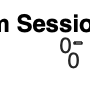

histogram(unitsTable.firing_rate);
xlabel('Firing Rate (Hz)');
ylabel('Number of Units');
title("Units from Session ID " + sessionUnderStudy.id);

While it's increasingly rare to find units (putative neurons) with high firing rates, there also exists a notable special population of units at the higher firing rates (30s, 40s, and 50s of Hz). 

### Examine Items Linked to Session

Each of the items linked to the session, including the units just explored, can be individually selected and examined.

#### Examine Unit Item

As with sessions, tablular indexing can be used to identify units meeting desired criteria, such as the brain region in which they were found:

% filter for units in the VISam brain area
filteredUnits = unitsTable(unitsTable.ephys_structure_acronym == 'VISam', :)

filteredUnits = 64x51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id         session_type          ephys_structure_acronym     L_ratio      age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio

Identified unit(s) can then be examined more closely: 

unitUnderStudy = bot.getUnits(filteredUnits(1, :))

unitUnderStudy =   Unit (VisualCoding) with properties:

         id: 951082938
       info: [1x1 struct]
    metrics: [1x1 struct]

   Linked Items
    session: [1x1 bot.item.concrete.EphysSession]
    channel: [1x1 bot.item.Channel]
      probe: [1x1 bot.item.Probe]


Unit items have a `metrics `property comprising all the computed characteristics (including the `firing_rate `explored above) of the computationally detected unit: 

disp(unitUnderStudy.metrics)

                              L_ratio: 0.0048
                          age_in_days: 134
                    air_channel_index: 195
                     amplitude_cutoff: 0.0164
    anterior_posterior_ccf_coordinate: 7530
                     cumulative_drift: 423.3400
                              d_prime: 3.5705
        dorsal_ventral_ccf_coordinate: 1062
                          firing_rate: 3.1213
                       isi_violations: 0.0116
                   isolation_distance: 64.8406
            left_right_ccf_coordinate: 7230
      lfp_temporal_subsampling_factor: 2
                            max_drift: 23.3100
                          nn_hit_rate: 0.9533
                         nn_miss_rate: 0.0027
                         peak_channel: 19
                       presence_ratio: 0.9900
            probe_horizontal_position: 27
              probe_lfp_sampling_rate: 1.2500e+03
                     silhouette_score: 0.0997
                                  snr: 2.8374
     

Among these metrics is the signal to noise ratio(SNR), which guides data consumers on how confidently to interpret the computationally detected unit.

#### Examine Probe Item

The session's ***probes*** can likewise be obtained and examined:

probesTable = sessionUnderStudy.probes;

% obtain a specific probe item to examine
probeUnderStudy = bot.getProbes(probesTable(1, :))

probeUnderStudy =   Probe (VisualCoding) with properties:

             id: 822645893
           info: [1x1 struct]
    linkedFiles: [1x1 table]

   Linked Items
        session: [1x1 bot.item.concrete.EphysSession]
       channels: [374x29 table]
          units: [65x51 table]

   Linked File Values ('LFPNWB')
        lfpData: '[download required]'
        csdData: '[download required]'


Probe items contain lower-frequency data known as *local field potentials (LFP*s), which is the basis for computed *cu.rrent source density (CSD) *data: 

probeUnderStudy.csdData

ans = struct with fields:
                   data: [3250x1 timetable]
    horizontalPositions: [384x1 double]
      verticalPositions: [384x1 double]


The LFP/CSD lower-frequency *wave* data complements the unit `firing_rate` data above (which track *spikes *highly localized in space & time*). *The [**Ephys Demo**](matlab:open('./demos\EphysDemo.mlx')) explores LFP/CSD wave data visualization further. 

#### Examine Channel Item

Finally, ***channels ***associated with the session (from across all its associated probes) can also be explored: 

channelsTable = sessionUnderStudy.channels

channelsTable = 1856x29 table
       id        ephys_probe_id    ephys_session_id    unit_count     name          session_type          ephys_structure_acronym    age_in_days    air_channel_index    anterior_posterior_ccf_coordinate    dorsal_ventral_ccf_coordinate    fail_eye_tracking    has_lfp_data    left_right_ccf_coordinate    lfp_sampling_rate    lfp_temporal_subsampling_factor    local_index    phase    probe_horizontal_position    probe_vertical_position    sampling_rate    sex    surface_channel_index    full_genotype    isi_experiment_id    date_of_a

With nearly 400 channels per probe, there are nearly 2000 channels of active data per session, which can be individually obtained and examined:

% obtain an array of channel items to examine
channelUnderStudy = bot.getChannels(channelsTable(1, :))

channelUnderStudy =   Channel (VisualCoding) with properties:

         id: 849789900
       info: [1x1 struct]

   Linked Items
    session: [1x1 bot.item.concrete.EphysSession]
      probe: [1x1 bot.item.Probe]
      units: [0x51 table]


Each channel item correspnds to a Neuropixels electrical contact with a unique anatomical position reported according to the Allen Mouse Brain Common Coordinate Framework (CCF) [3]:

channelCCFLocation= [channelUnderStudy.info.anterior_posterior_ccf_coordinate channelUnderStudy.info.dorsal_ventral_ccf_coordinate]

channelCCFLocation = 1x2 uint32 row vector
   8098   4303


### Learn More

For an example of more in-depth neural data analysis of the Visual Coding Neuropixels dataset using the Brain Observatiory Toolbox, see the [**Ephys Demo**](matlab:open('../demos/EphysDemo.mlx')).

For more detailed guidance on how to use the Brain Observatory Toolbox with the Visual Coding Neuropixels dataset, see the [**Ephys Tutorial**](matlab:open('../tutorials/EphysTutorial.mlx')).

### References

[1] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[3] Wang, Quanxin et al. “The Allen Mouse Brain Common Coordinate Framework: A 3D Reference Atlas.” *Cell* vol. 181,4 (2020): 936-953.e20. [doi:10.1016/j.cell.2020.04.007](doi:10.1016/j.cell.2020.04.007https://doi.org/10.1016/j.cell.2020.04.007). 